**Question 1:**

What do you expect the results to look like and why? Compare the size of dxtools with the size of tools. Why are these sizes different? 

**Answer:**

    My expectation on the results be that there is only edges showed in the figure. Because our image few256 has a larger contrast between black and white, therefore, the edge might be clear. On the other hand, when we apply simple difference and central difference, I expect to have a much more clear edge on the direction I differentiate.

    I use a 3x3 kernel to implement the differentiation and I found that my size of *dxtools* and *dytools* is less than my initial figure because of the function parameter. we use 'valid' as the shape parameter, which only returns those parts of the convolution that are computed without the zero-padded edges.Therefore we don't calculate the corner because there is no next / previous element among them. In our case the size changes from (256,256) to (254,254).

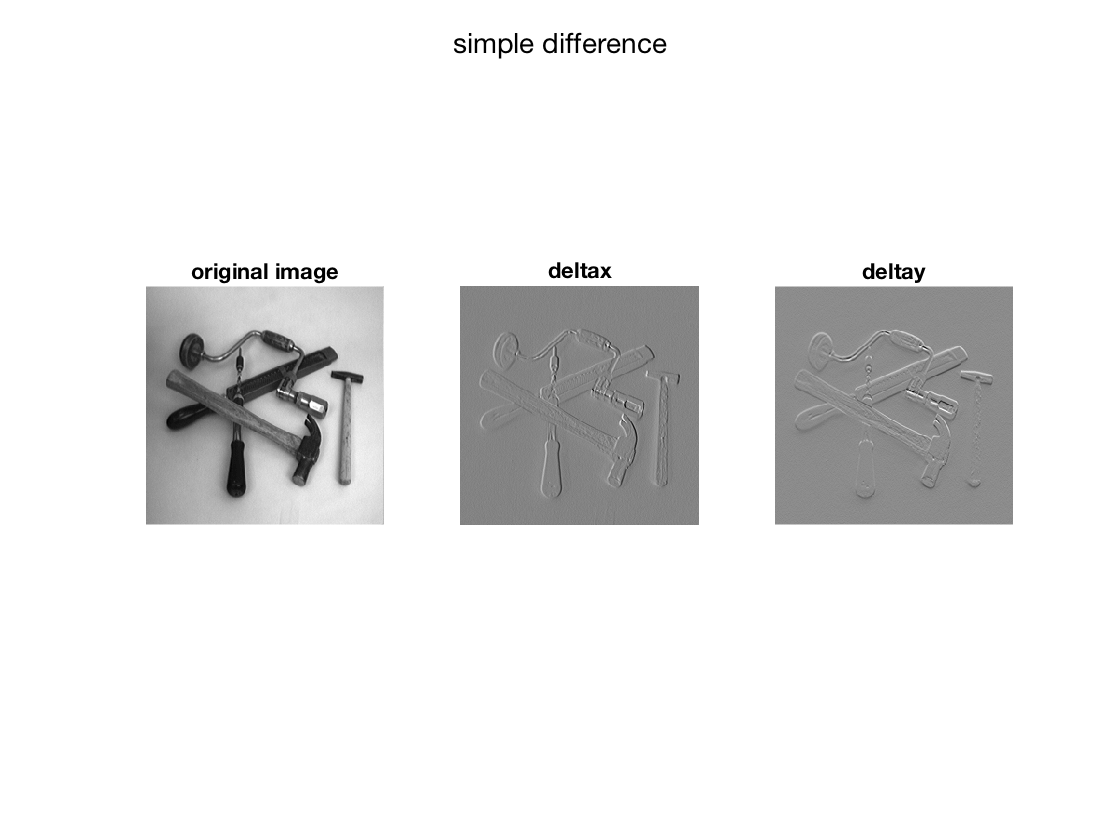

tools = few256;
figure
suptitle('simple difference')
subplot(1,3,1)
showgrey(tools)
title('original image')
subplot(1,3,2)
deltax = [0 0 0;0 -1 1;0 0 0];
dxtools = conv2(tools, deltax, 'valid');
showgrey(dxtools)
title('deltax')
subplot(1,3,3)
deltay = [0 0 0;0 -1 0;0 1 0];
dytools = conv2(tools, deltay, 'valid');
showgrey(dytools)
title('deltay')

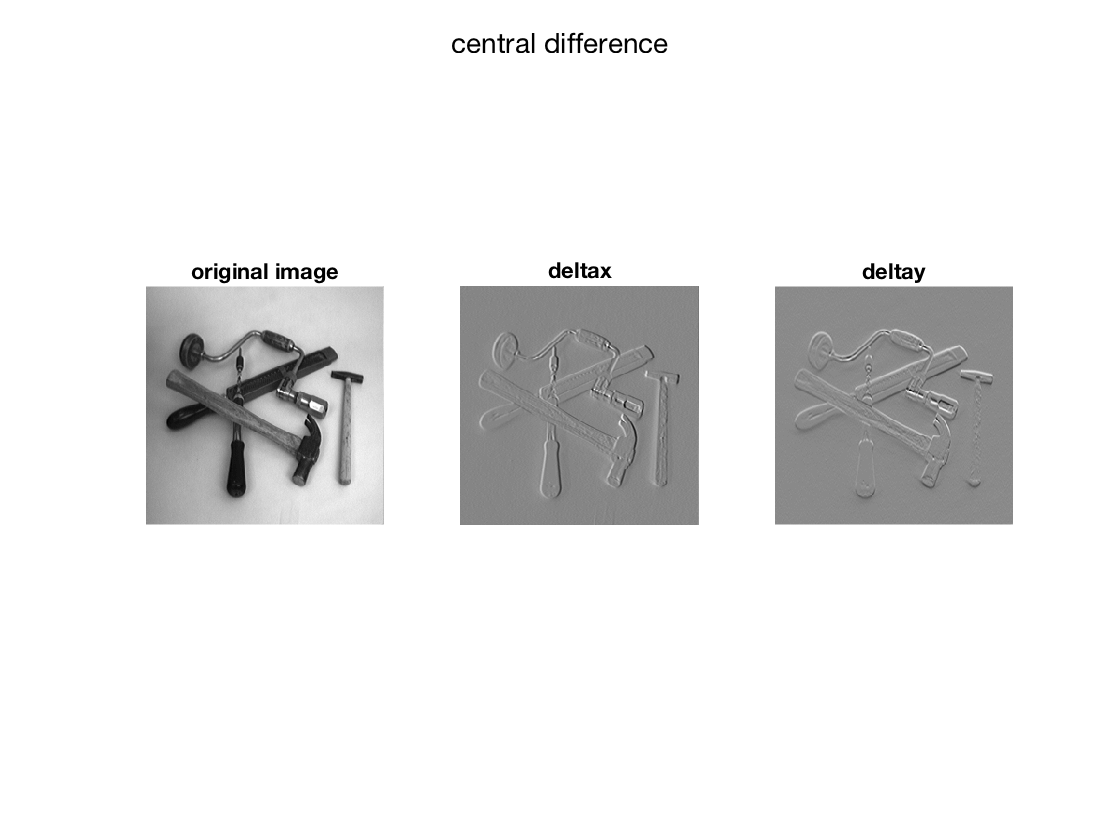


figure 
suptitle('central difference')
subplot(1,3,1)
showgrey(tools)
title('original image')
subplot(1,3,2)
deltax = [0 0 0;-0.5 0 0.5;0 0 0];
dxtools = conv2(tools, deltax, 'valid');
showgrey(dxtools)
title('deltax')
subplot(1,3,3)
deltay = [0 -0.5 0;0 0 0;0 0.5 0];
dytools = conv2(tools, deltay, 'valid');
showgrey(dytools)
title('deltay')

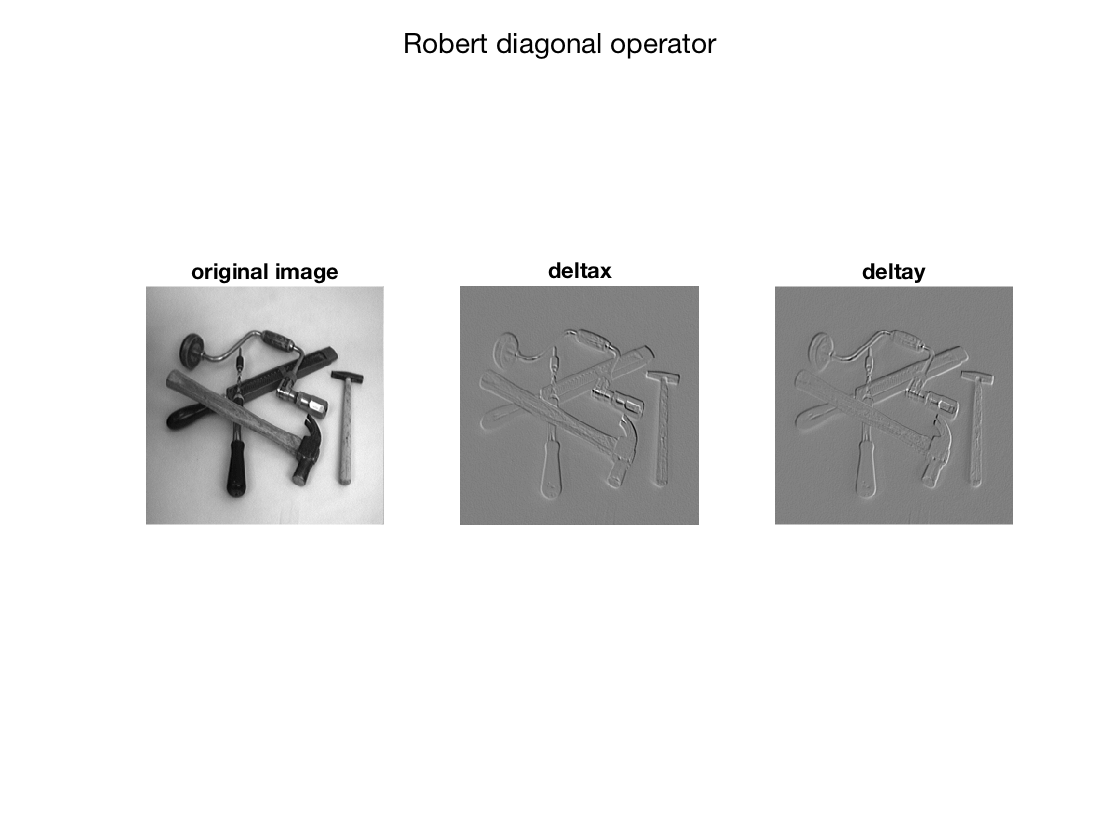


figure 
suptitle('Robert diagonal operator')
subplot(1,3,1)
showgrey(tools)
title('original image')
subplot(1,3,2)
deltax = [0 0 0;0 0 1;0 -1 0];
dxtools = conv2(tools, deltax, 'valid');
showgrey(dxtools)
title('deltax')
subplot(1,3,3)
deltay = [0 0 0;0 1 0;0 0 -1];
dytools = conv2(tools, deltay, 'valid');
showgrey(dytools)
title('deltay')

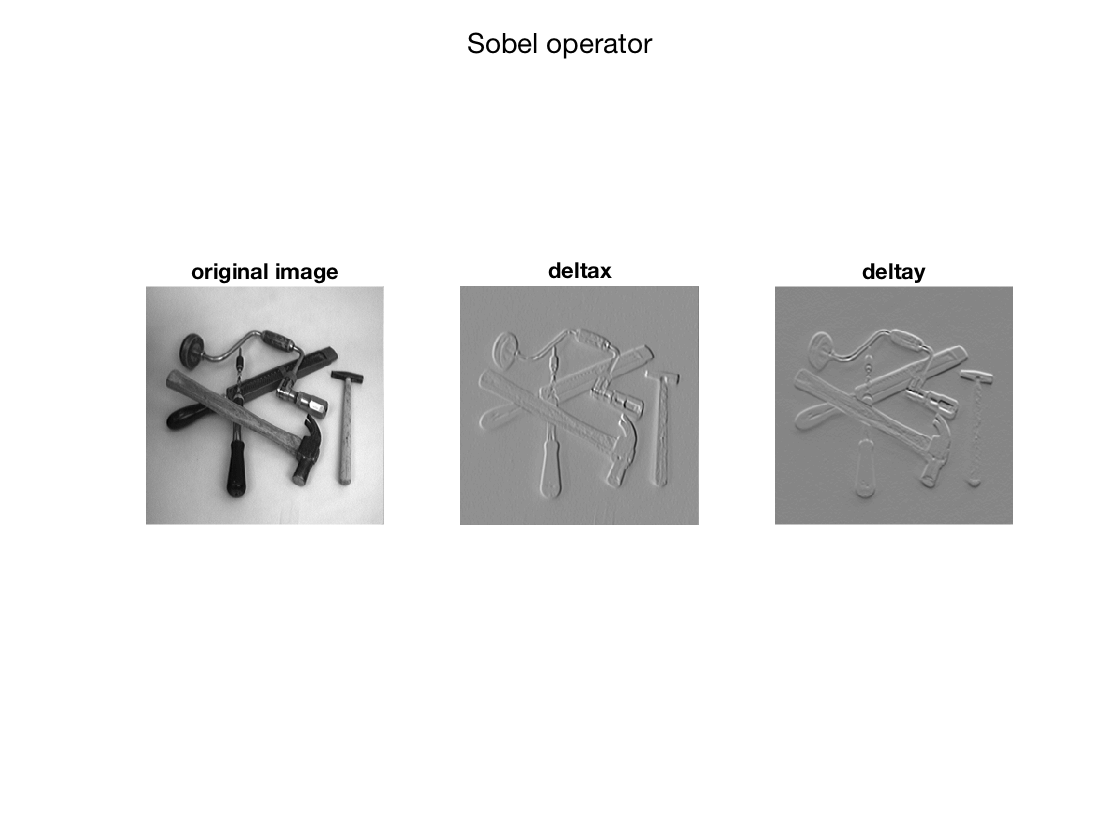


figure 
suptitle('Sobel operator')
subplot(1,3,1)
showgrey(tools)
title('original image')
subplot(1,3,2)
deltax = [-1 0 1;-2 0 2;-1 0 1];
dxtools = conv2(tools, deltax, 'valid');
showgrey(dxtools)
title('deltax')
subplot(1,3,3)
deltay = [-1 -2 -1;0 0 0;1 2 1];
dytools = conv2(tools, deltay, 'valid');
showgrey(dytools)
title('deltay')

**Question 2 :**		

Is it easy to find a threshold that results in thin edges? Explain why or why not! 

**Answer:**

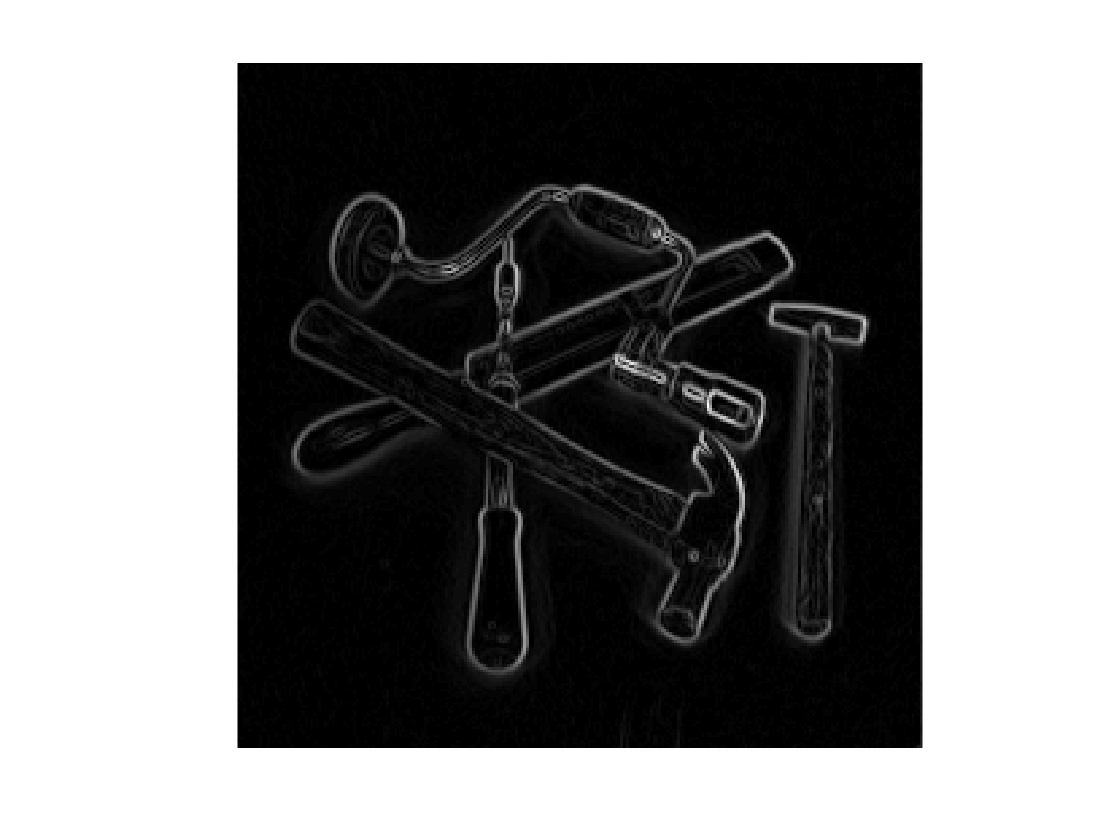

gradmagntools = sqrt(dxtools .^2 + dytools .^2);
figure
showgrey(gradmagntools)

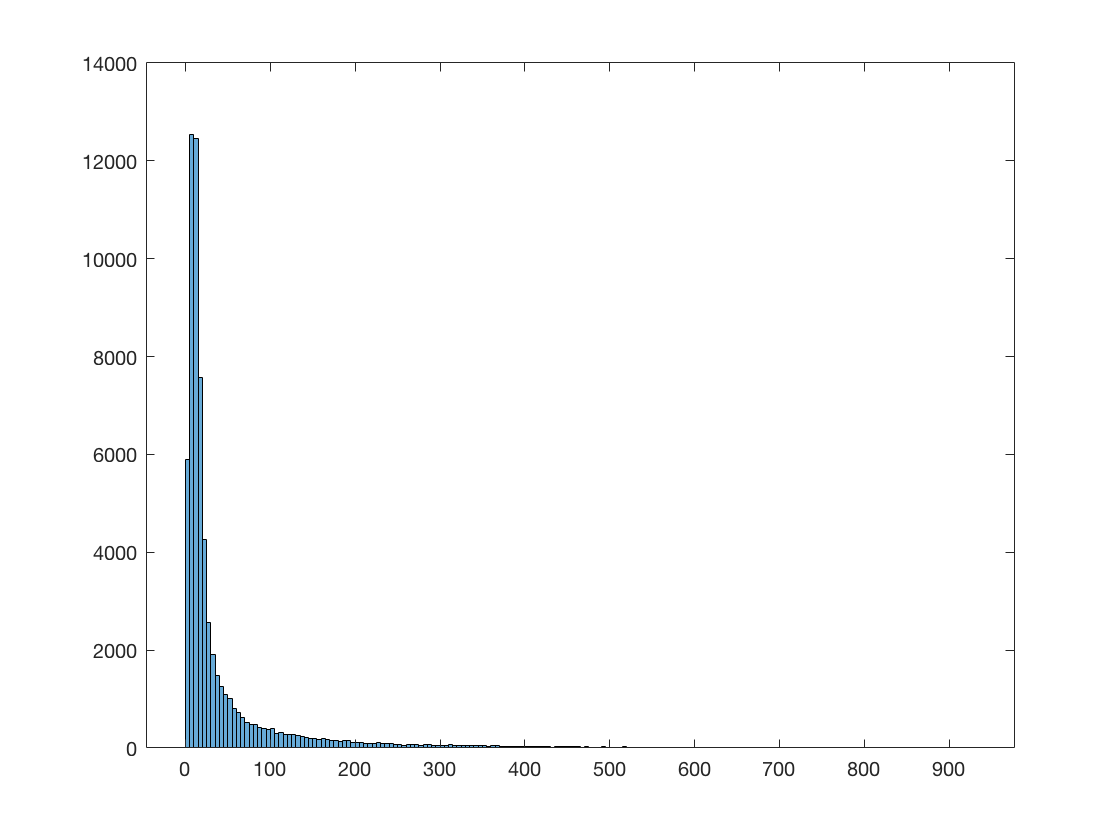

figure;
histogram(gradmagntools);

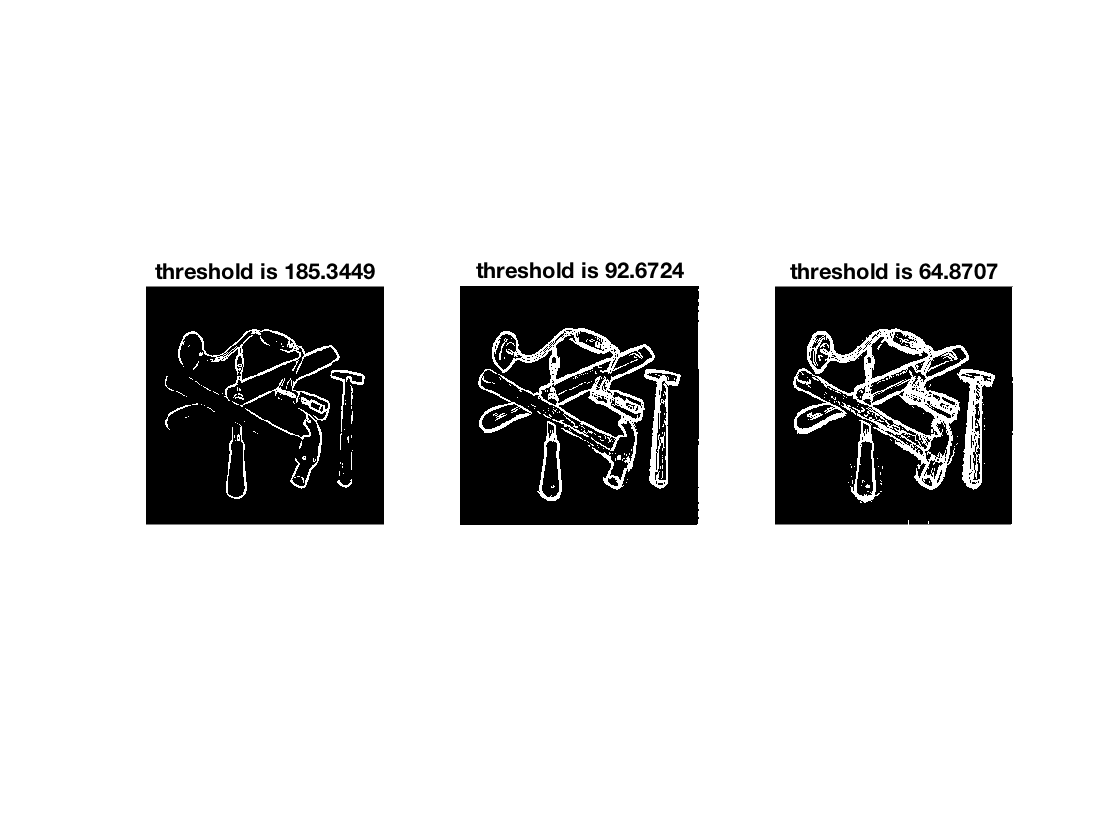

figure
subplot(1,3,1)
threshold = max(gradmagntools(:)) * 0.2;
showgrey((gradmagntools - threshold) > 0)
title(['threshold is ' num2str(threshold)])
subplot(1,3,2)
threshold = max(gradmagntools(:)) * 0.1;
showgrey((gradmagntools - threshold) > 0)
title(['threshold is ' num2str(threshold)])
subplot(1,3,3)
threshold = max(gradmagntools(:)) * 0.07;
showgrey((gradmagntools - threshold) > 0)
title(['threshold is ' num2str(threshold)])

It is not easy to find a suitable threshold. This is because if the threshold is too low, there will be many maxima due to noise; if the threshold is too high, the weak edge might be disconnected as the figure here shows. So we have to find a threshold that can greatly filter out the noise while remain the weak edge.

**Question 3:**

Does smoothing the image help to find edges? 

**Answer:**

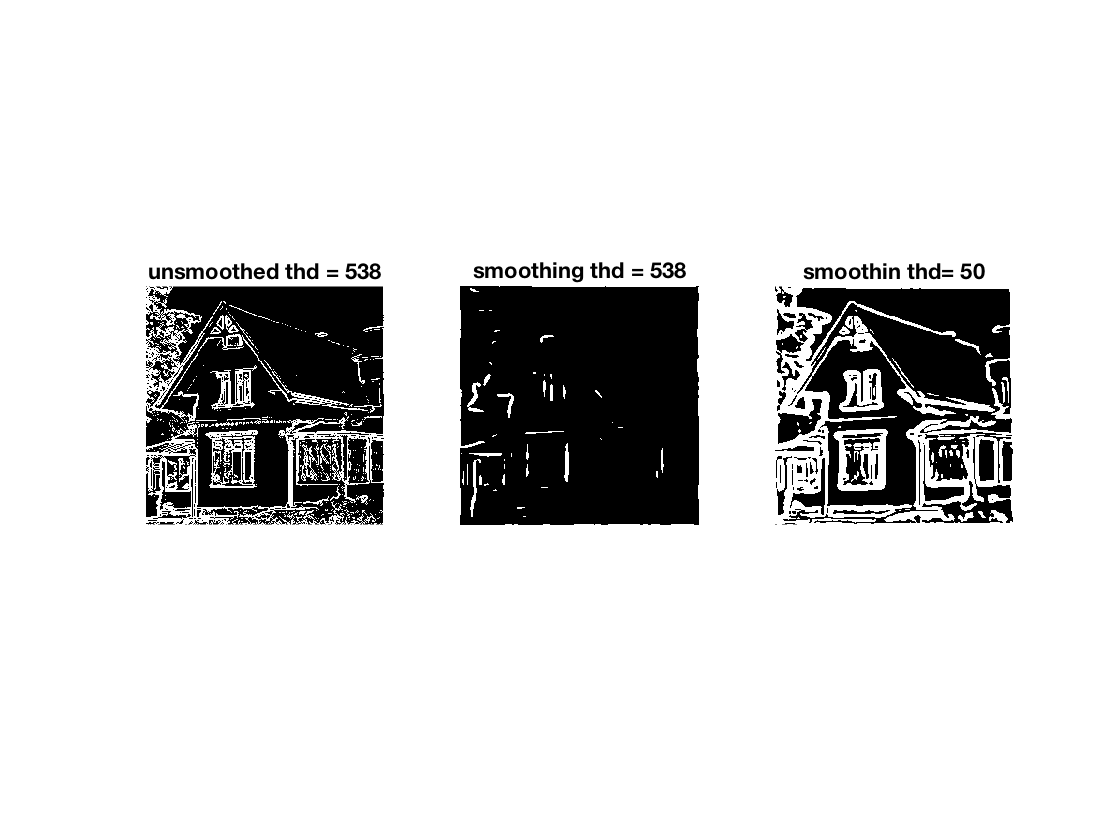

%%% before smooth
god = Lv(godthem256,'valid');
figure
subplot(1,3,1)
threshold = 538;
showgrey((god - threshold) > 0)
title(['unsmoothed thd = ' num2str(threshold)])

%%% after smoothing (sigma = 4)
godsmooth = LvSmooth(godthem256,'valid',4);
subplot(1,3,2)
threshold = 538;
showgrey((godsmooth - threshold) > 0)
title(['smoothing thd = ',num2str(threshold)])
subplot(1,3,3)
threshold =50;
showgrey((godsmooth - threshold) > 0)
title(['smoothin thd= ',num2str(threshold) ])

Smoothing the image does help to find edges because it removes the local maxima and we don't need such high threshold to find the edge. The figure below shows the comparison between smoothed and unsmoothed image. 

The left figure below is the unsmoothed image with the threshold equals to 538, and the image in the middle is the image smoothed by Gaussian filter with sigma equals 4 and the threshold is 538 as well. By comparing the left and middle image, we found that we don't need a threshold as high as we used in the unsmoothed image. The threshold = 50 is used in the right image and there is obviously more clear edge in right image than in middle image. Besides, the edge in the smoothed image is much thicker than the edge in the unsmoothed image. However, it is much difficult to find the threshold after smoothing the image.

**Question 4 :**

What can you observe? Provide explanation based on the generated images. Study the sign of the third order derivative in the gradient direction by loading the image *tools = few256*

and show the result of *showgrey(Lvvvtilde(discgaussfft(tools, scale), ’same’) < 0)*

for the same values of scale. What is the effect of the sign condition in this differential expression? 

**Answer:**

The white lines in the figure below is the third derivative of the image few256. We can see that the edges are no longer clear.  If we choose larger scale, we can recognize edges more clearly. However, if we choose too large scale, the white lines are much thicker, and some of the pixels near the edge is considered as a part of edge and we the edge is no longer accurate.

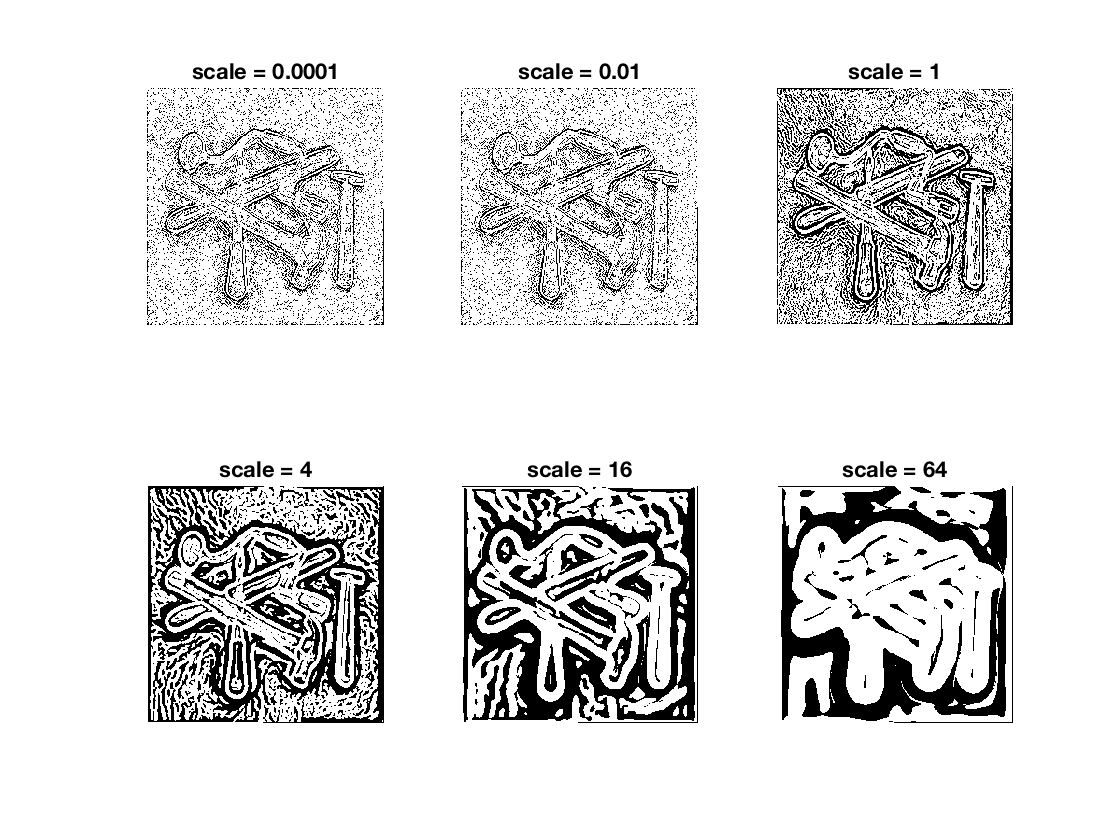

tools = few256;


figure
subplot(2,3,1)
scale = 0.0001;
showgrey(Lvvvtilde(discgaussfft(tools,scale),'same') < 0)
title(['scale = ' num2str(scale)])

subplot(2,3,2)
scale = 0.01;
showgrey(Lvvvtilde(discgaussfft(tools,scale),'same') < 0)
title(['scale = ' num2str(scale)])

subplot(2,3,3)
scale = 1;
showgrey(Lvvvtilde(discgaussfft(tools,scale),'same') < 0)
title(['scale = ' num2str(scale)])

subplot(2,3,4)
scale = 4;
showgrey(Lvvvtilde(discgaussfft(tools,scale),'same') < 0)
title(['scale = ' num2str(scale)])

subplot(2,3,5)
scale = 16;
showgrey(Lvvvtilde(discgaussfft(tools,scale),'same') < 0)
title(['scale = ' num2str(scale)])

subplot(2,3,6)
scale = 64;
showgrey(Lvvvtilde(discgaussfft(tools,scale),'same') < 0)
title(['scale = ' num2str(scale)])

**Question 5 :**

    Assemble the results of the experiment above into an illustrative collage with the subplot command. Which are your observations and conclusions? 

**Answer:**

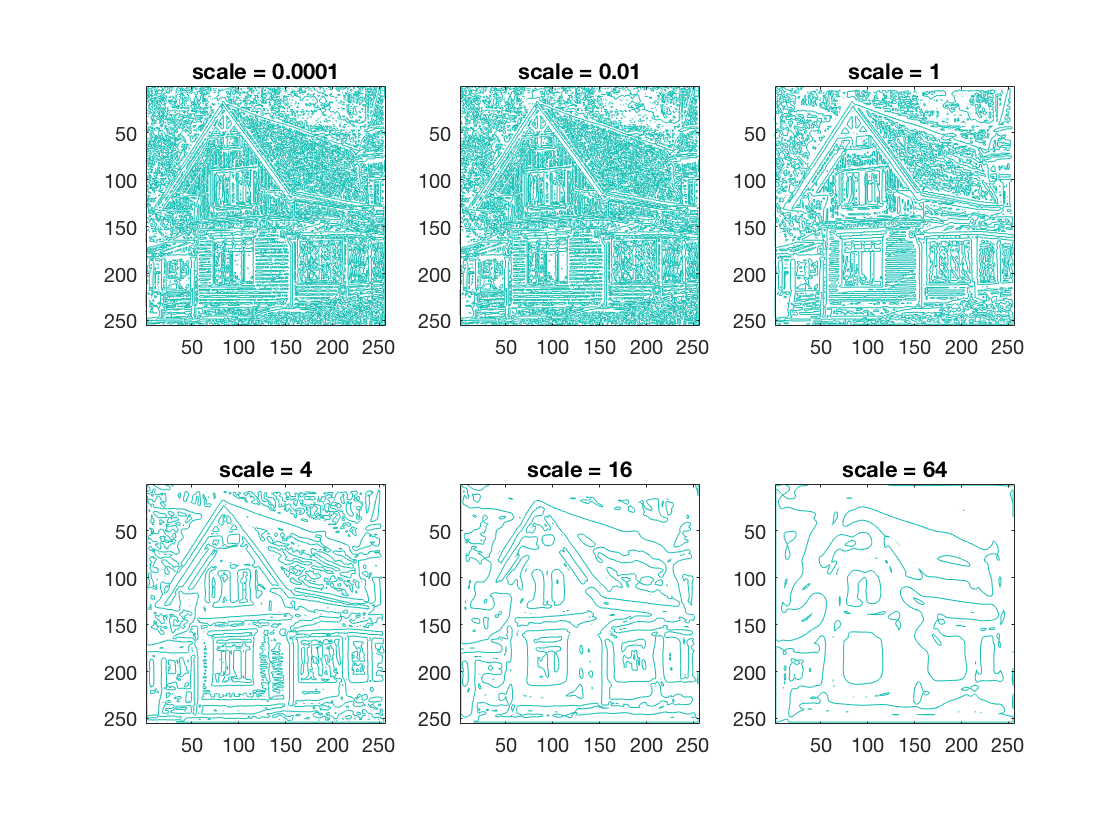

house = godthem256;

figure
subplot(2,3,1)
scale = 0.0001;
contour(Lvvtilde(discgaussfft(house, scale), 'same'), [0 0])
axis('image')
axis('ij')
title(['scale = ' num2str(scale)])

subplot(2,3,2)
scale = 0.01;
contour(Lvvtilde(discgaussfft(house, scale), 'same'), [0 0])
axis('image')
axis('ij')
title(['scale = ' num2str(scale)])

subplot(2,3,3)
scale = 1;
contour(Lvvtilde(discgaussfft(house, scale), 'same'), [0 0])
axis('image')
axis('ij')
title(['scale = ' num2str(scale)])

subplot(2,3,4)
scale = 4;
contour(Lvvtilde(discgaussfft(house, scale), 'same'), [0 0])
axis('image')
axis('ij')
title(['scale = ' num2str(scale)])

subplot(2,3,5)
scale = 16;
contour(Lvvtilde(discgaussfft(house, scale), 'same'), [0 0])
axis('image')
axis('ij')
title(['scale = ' num2str(scale)])

subplot(2,3,6)
scale = 64;
contour(Lvvtilde(discgaussfft(house, scale), 'same'), [0 0])
axis('image')
axis('ij')
title(['scale = ' num2str(scale)])

In the figure below, the green lines are the pixels whose second derivative is 0. we can find that when the scale is small in the Gaussian filter, it is hard to see any edge because there are still many local maxima left. The image will contain more details such as texture, noise and so on, so we can hardly find a clear edge. If we choose a larger value of scale, we can see some edge emerge, and can recognize the edge. If we choose too larger value of scale, we can see that some edge is faded and distorted that is not exactly what we want.

**Question 6 :**

    How can you use the response from L ̃vv to detect edges, and how can you improve the result by using 

L ̃vvv?

**Answer:**

If we would like to use the response from *Lvv* to detect edges, we should first smooth the image with a proper scale. Then we take only the pixels with their second derivatives is 0 as edge. 

If we want to improve the result by using *Lvvv*, we can pick the pixels which not only their second derivatives are 0 but also their third derivatives are smaller than 0 to remove more isolated points (noise) which we don't consider them as edges.

        The edge can be defined as below:

                            Lvv = 0

                            Lvvv < 0

**Question 7 :**

    Present your best results obtained with extractedge for house and tools. 	

**Answer: **

figure
tools = few256;
scale = 5;
threshold = 20;
x = extractedge(tools, scale,threshold, 'same');

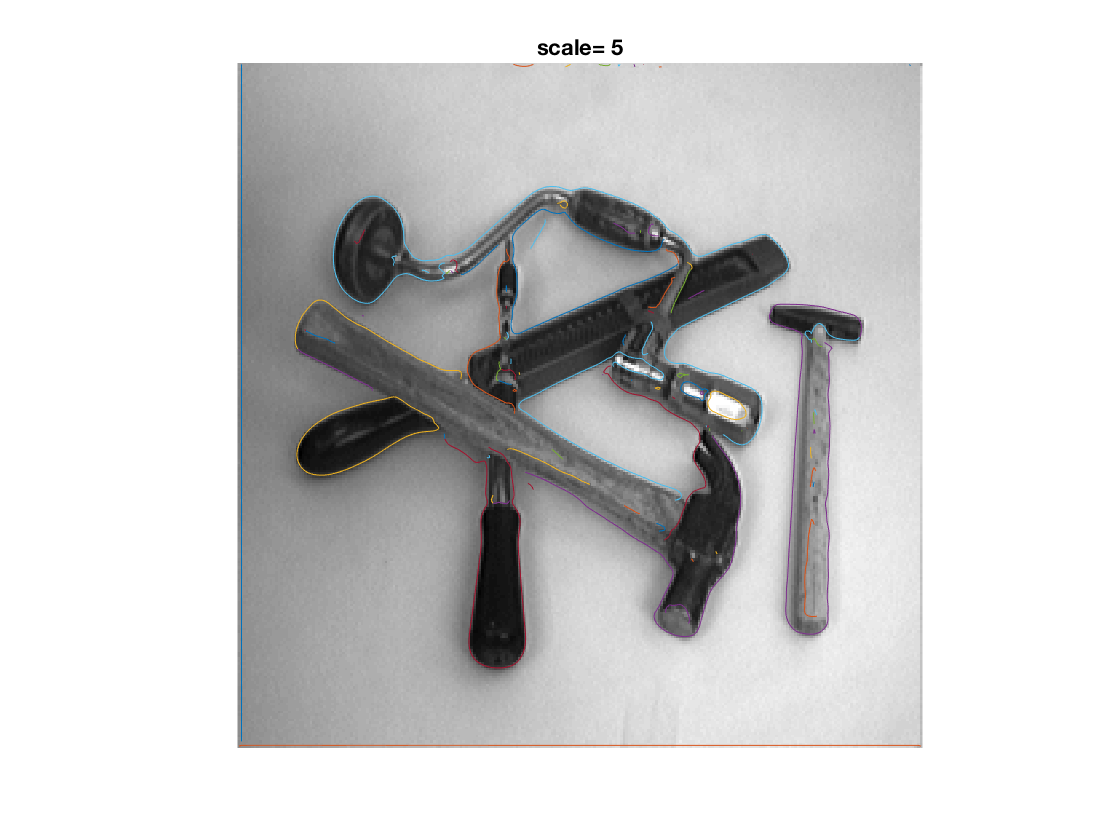

title(['scale= ' num2str(scale)])

figure
house = godthem256;
scale = 2;
threshold = 100;
x = extractedge(house, scale,threshold, 'same');

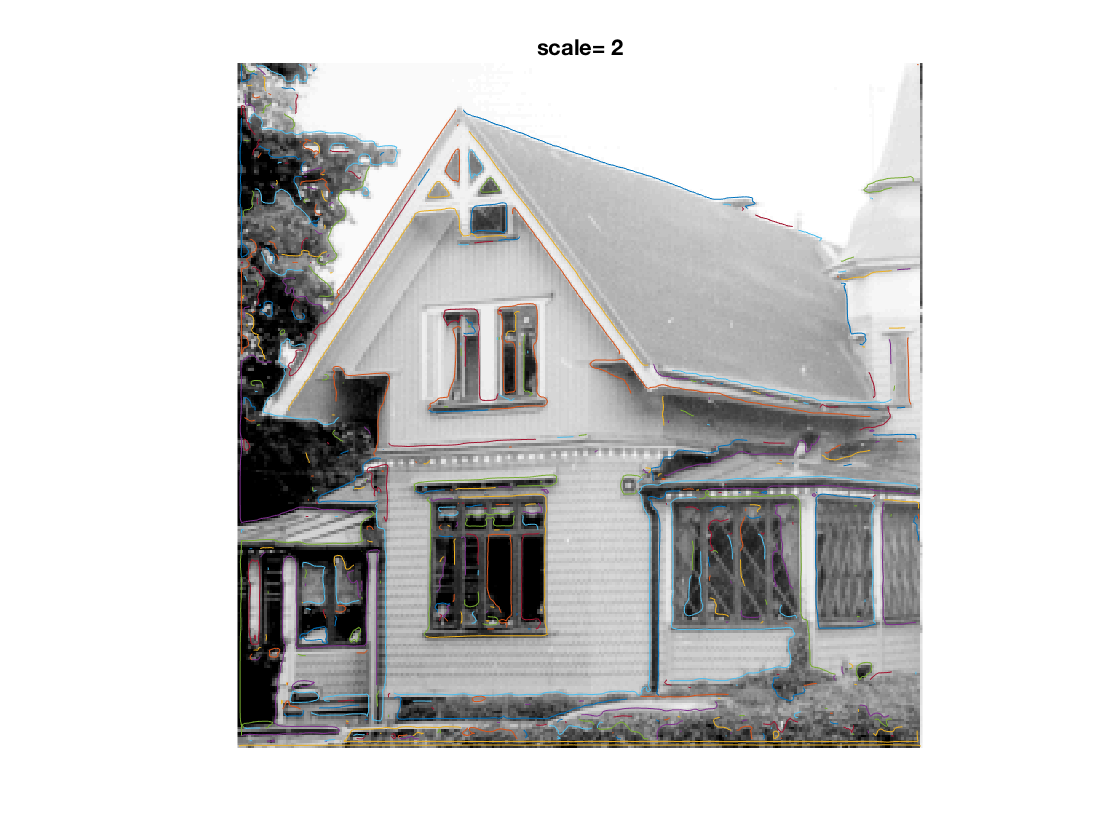

title(['scale= ' num2str(scale)])

**Question 8 :**

    Identify the correspondences between the strongest peaks in the accumulator and line segments in the output image. Doing so convince yourself that  the implementation is correct. Summarize the results in one or more figures. 

**Answer:**

In this question, we are going to use the figures ***triangle128, houghtest256 ***to identify the correspondences between the strongest peaks in the accumulator and line segments in the output image and then use  ***few256 ***and ***phonecalc256 ***to test my code.

1.***triangle128 ***

rho = 40.9340

theta = -0.4826

rho = 111.8863

theta = 0.0088

rho = 8.1868

theta = 1.5357

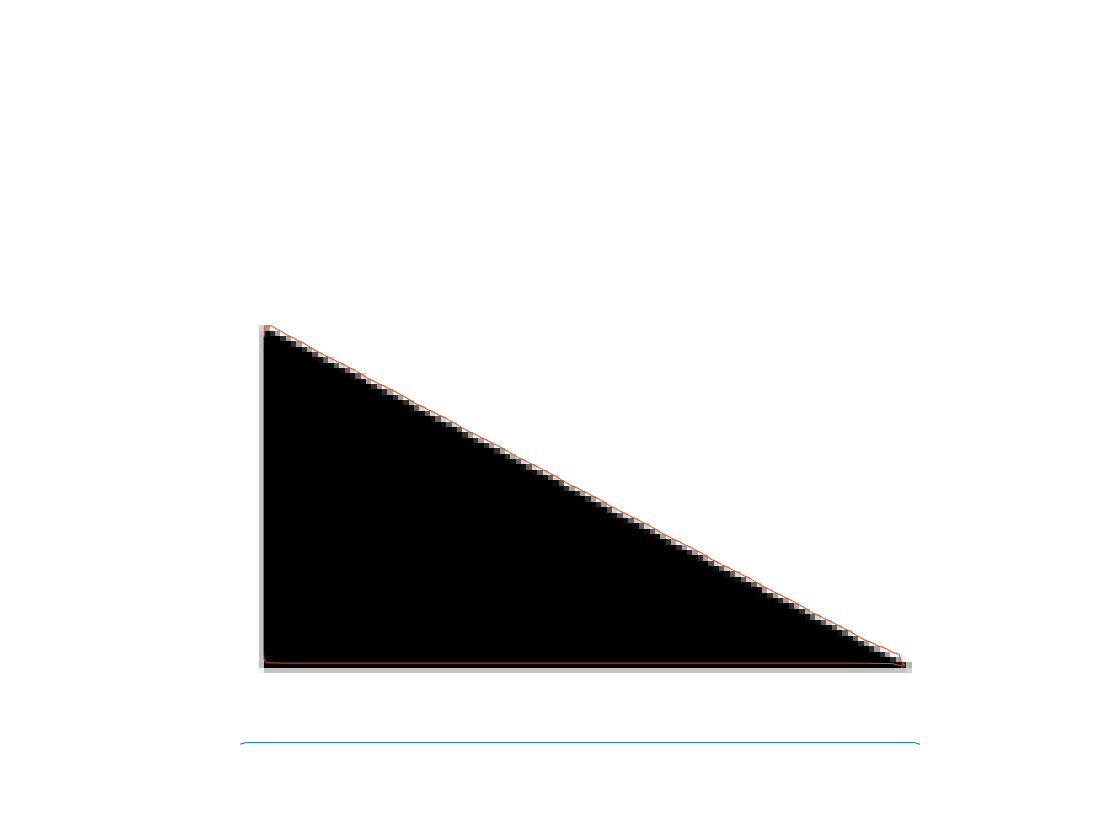

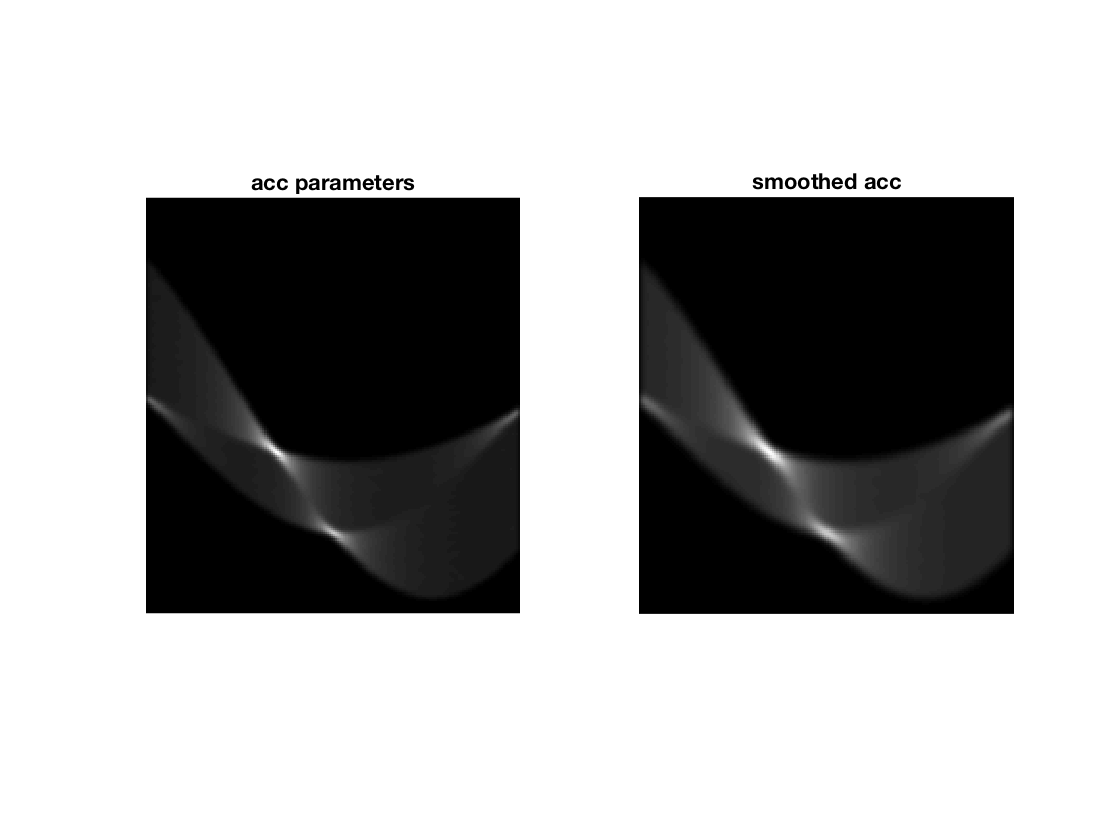

testimage1 = triangle128;
scale = 2;
gradmagnthreshold = 5;
nrho = 200;
ntheta = 180;
nlines = 3;
verbose = 2;
verbose_edge = 1;
[linepar,acc] = houghedgeline(testimage1,scale,gradmagnthreshold,nrho,ntheta,nlines,verbose,verbose_edge);

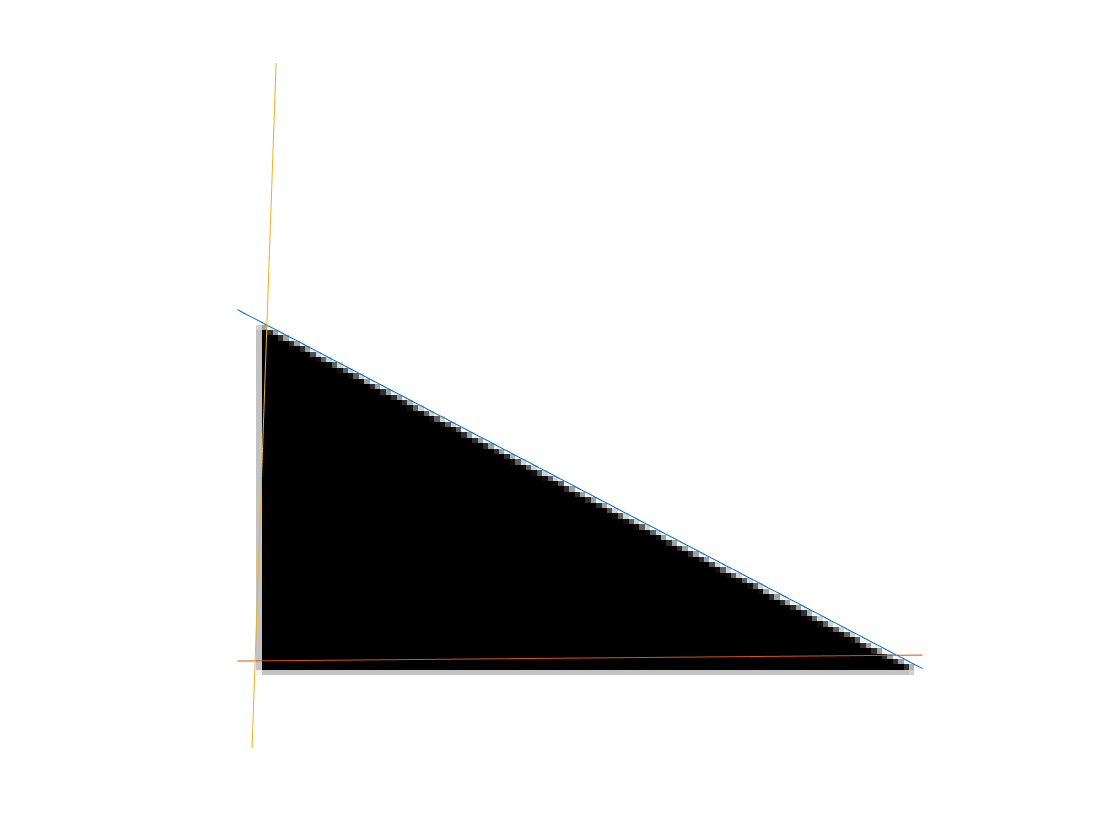

figure
visualize_edge(testimage1,linepar);

2.***houghtest256***

rho = 86.3379

theta = -0.4069

rho = 267.7200

theta = 0.3544

rho = 266.2689

theta = 0.3369

rho = 269.1710

theta = 0.3719

rho = 138.5759

theta = 0.9495

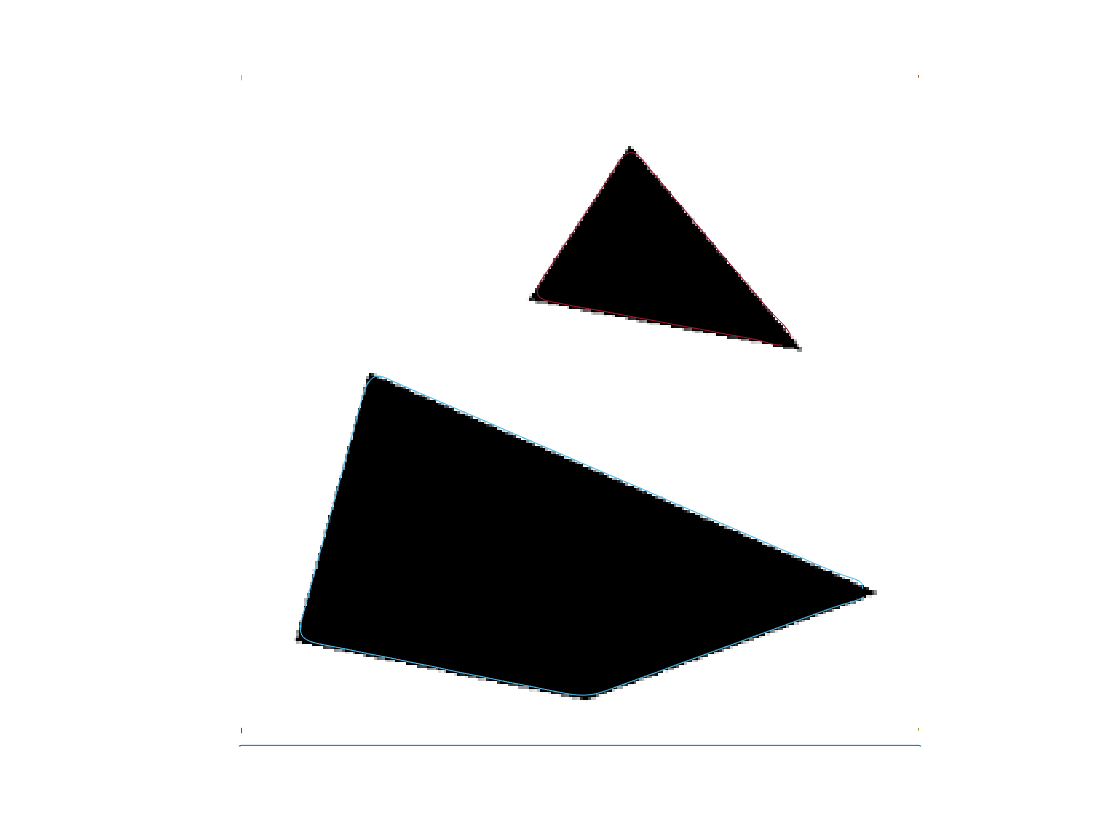

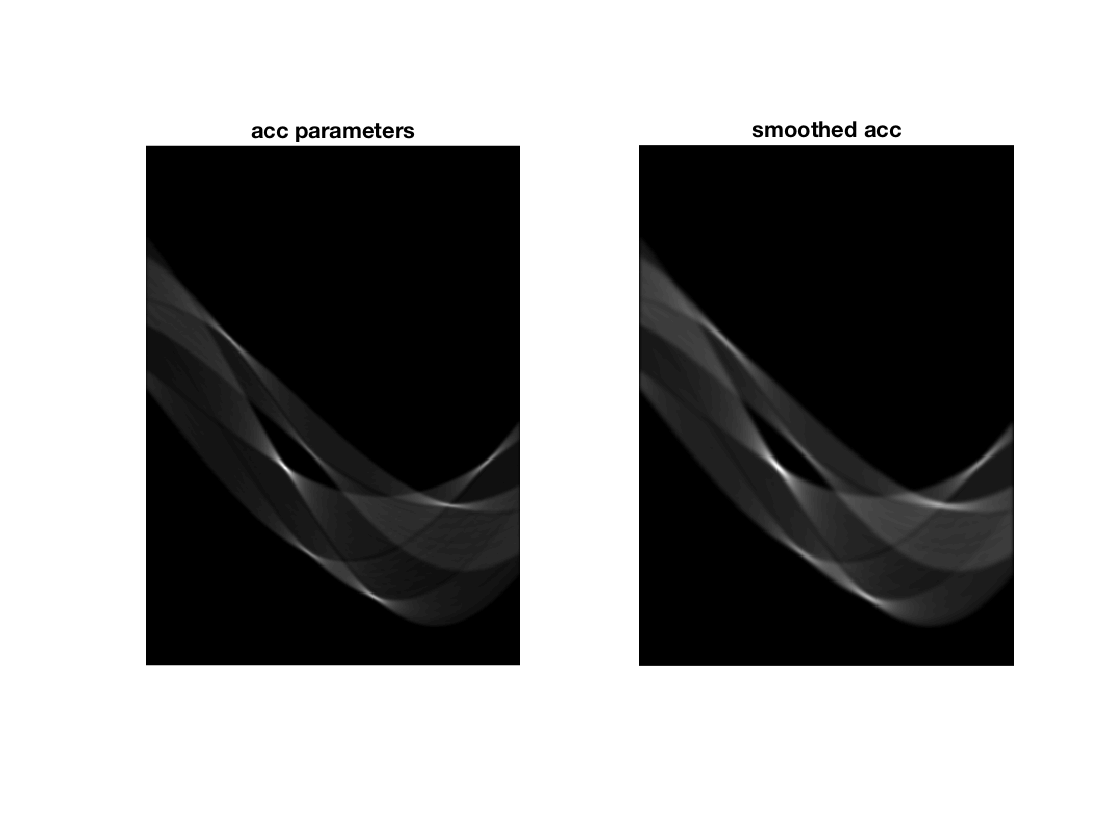

testimage1 = houghtest256;
smalltest = binsubsample(testimage1);
scale = 16;
gradmagnthreshold = 250;
nrho = 500;
ntheta = 360;
nlines = 5;
verbose = 2;
verbose_edge = 1;
[linepar,acc] = houghedgeline(testimage1,scale,gradmagnthreshold,nrho,ntheta,nlines,verbose,verbose_edge);

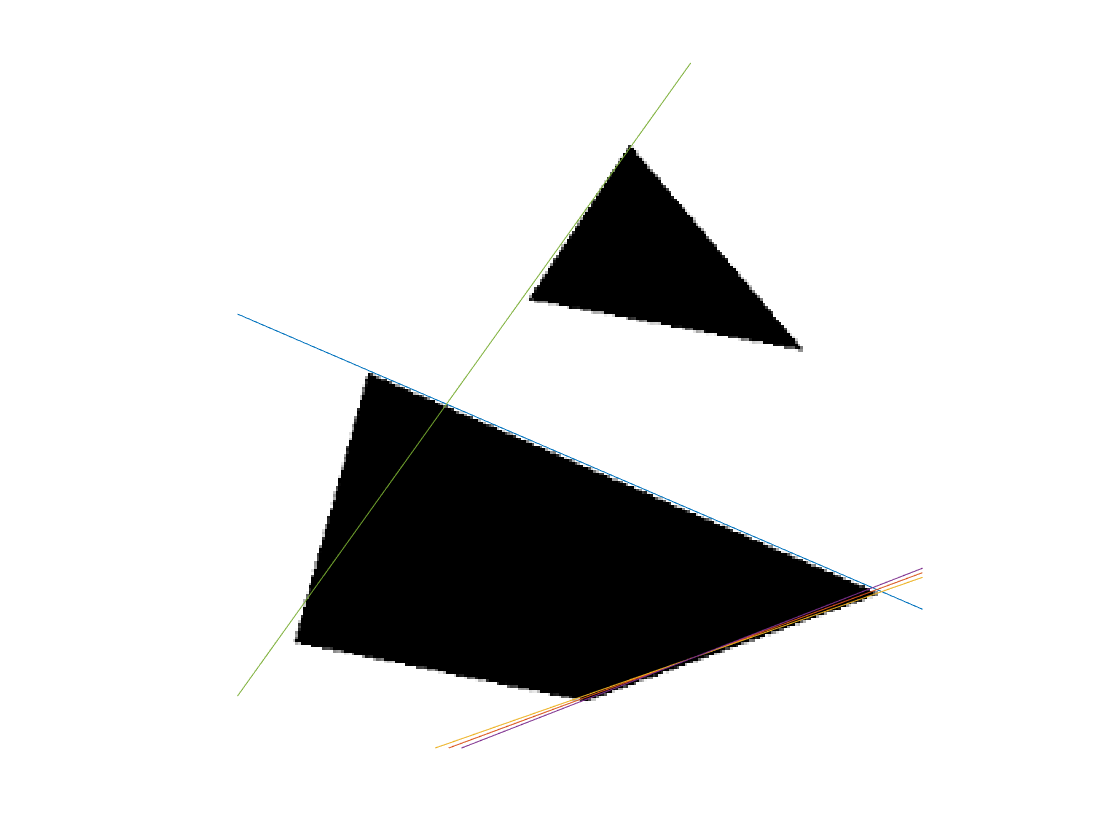

visualize_edge(testimage1,linepar);

3.***few256***

rho = 135.6738

theta = 0.4157

rho = 63.1210

theta = -0.5032

rho = 64.5720

theta = -0.4857

rho = 34.0998

theta = -0.4594

rho = 154.5375

theta = 0.3894

rho = 81.9847

theta = -0.5032

rho = 132.7717

theta = 0.1356

rho = 21.0403

theta = -0.5207

rho = 16.6872

theta = -0.5469

rho = 109.5548

theta = 1.4658

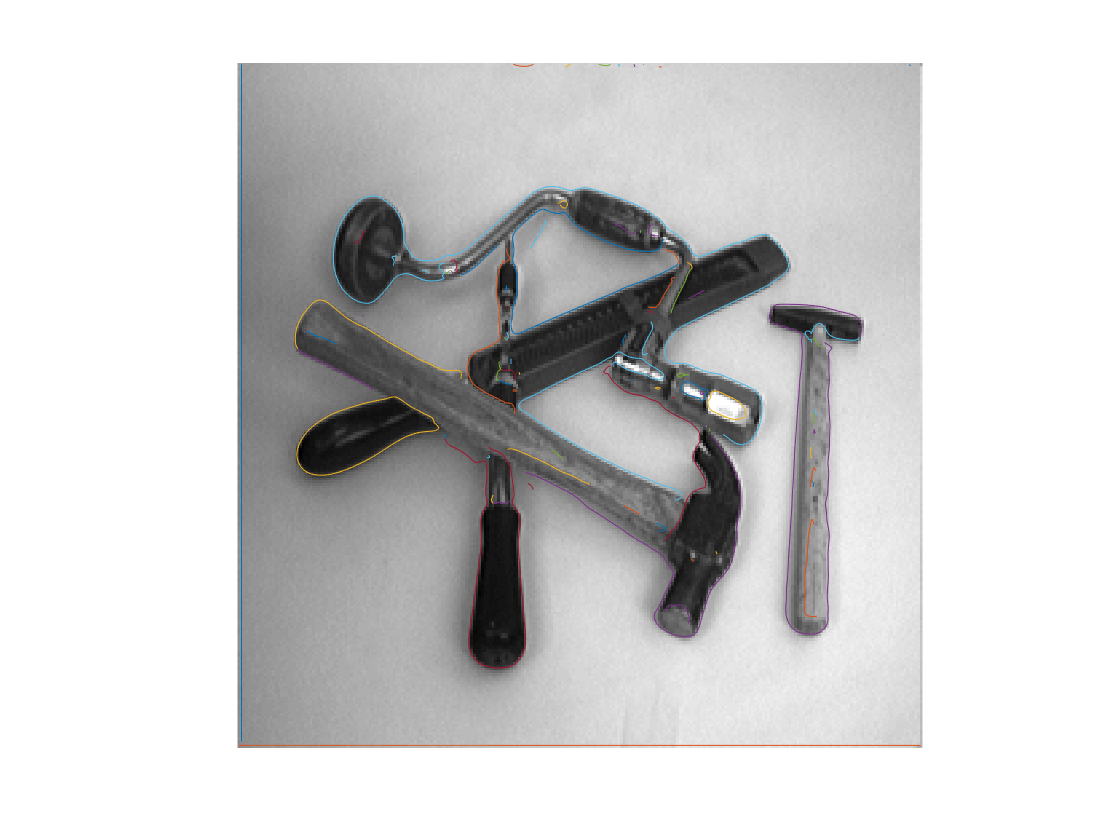

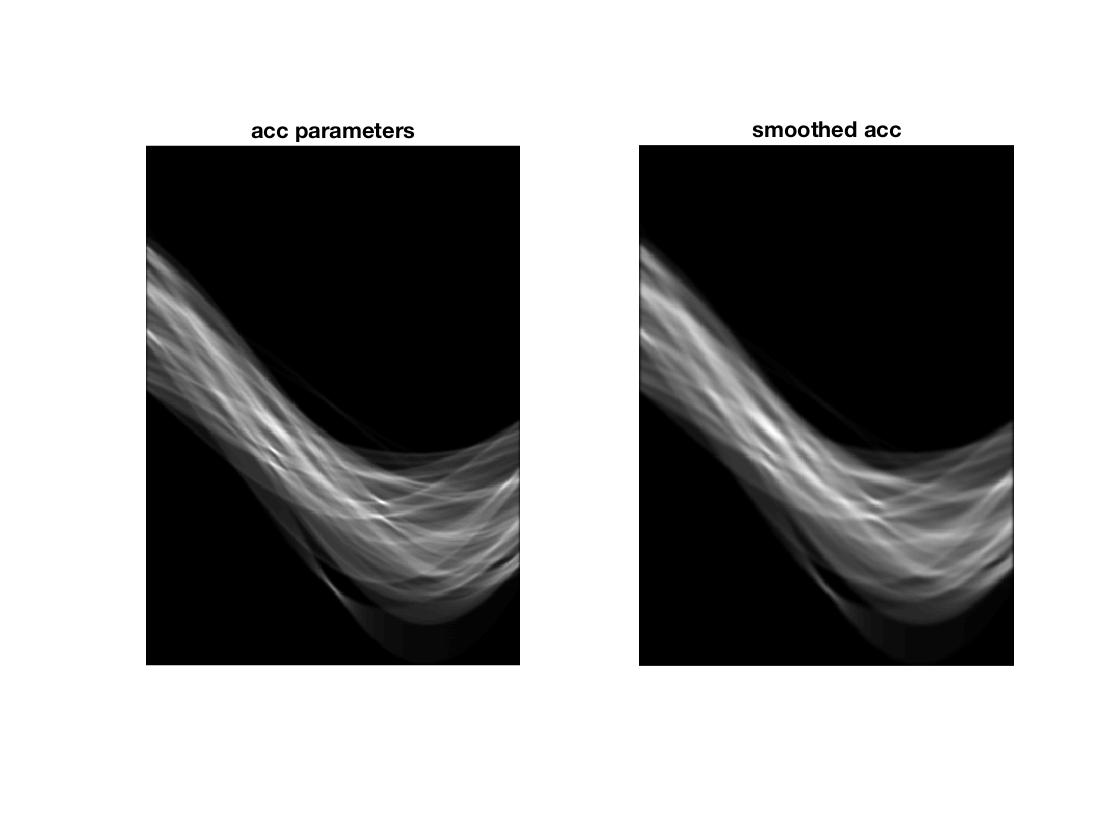

testimage1 = few256;
scale = 5;
gradmagnthreshold = 20;
nrho = 500;
ntheta = 360;
nlines = 10;
verbose = 2;
verbose_edge = 1;
[linepar,acc] = houghedgeline(testimage1,scale,gradmagnthreshold,nrho,ntheta,nlines,verbose,verbose_edge);

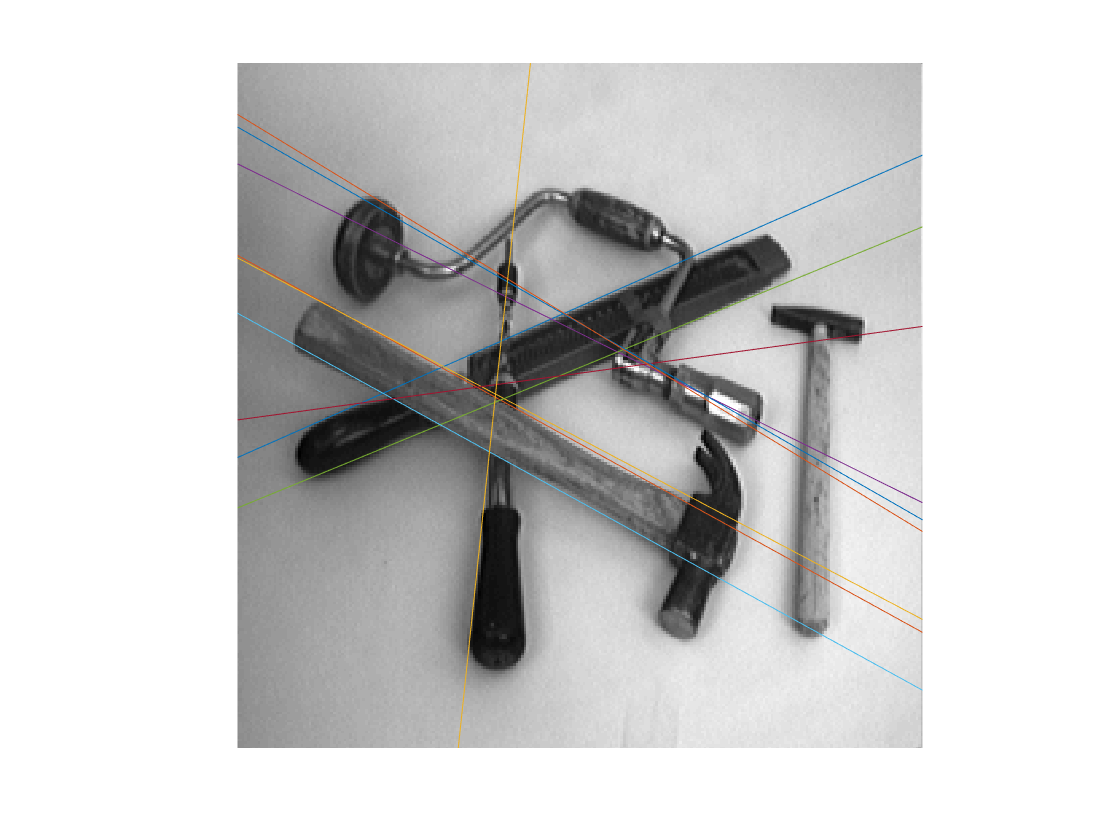

visualize_edge(testimage1,linepar);

4.***phonecalc256 ***

rho = 174.4643

theta = 0.2369

rho = -31.2624

theta = -1.3251

rho = -45.3809

theta = -1.4304

rho = -51.4317

theta = -1.4830

rho = 105.8887

theta = 0.5529

rho = 136.1427

theta = -0.3949

rho = 65.5502

theta = 1.5181

rho = 97.8210

theta = -0.5353

rho = 93.7872

theta = -0.5529

rho = 148.2442

theta = 0.7986

rho = 87.7364

theta = 0.2369

rho = 230.9383

theta = 1.1145

rho = 261.1922

theta = 1.3602

rho = 89.7533

theta = 0.2720

rho = 164.3797

theta = -0.2896

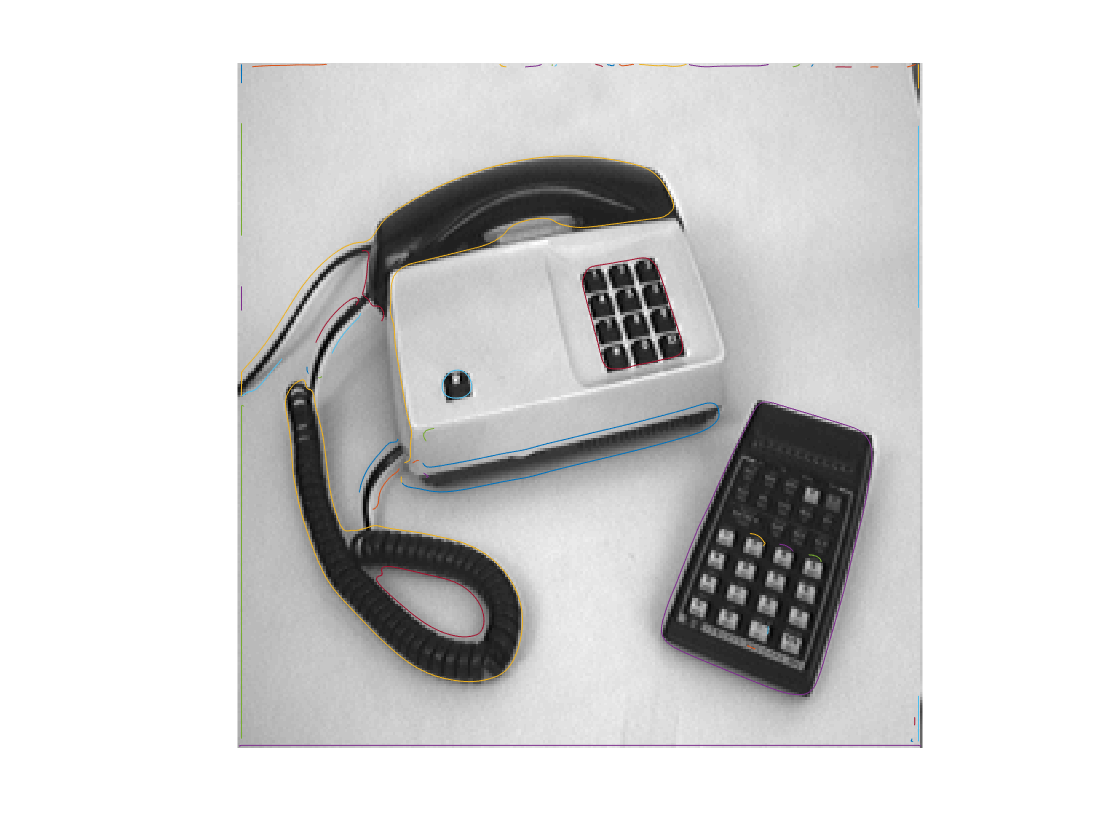

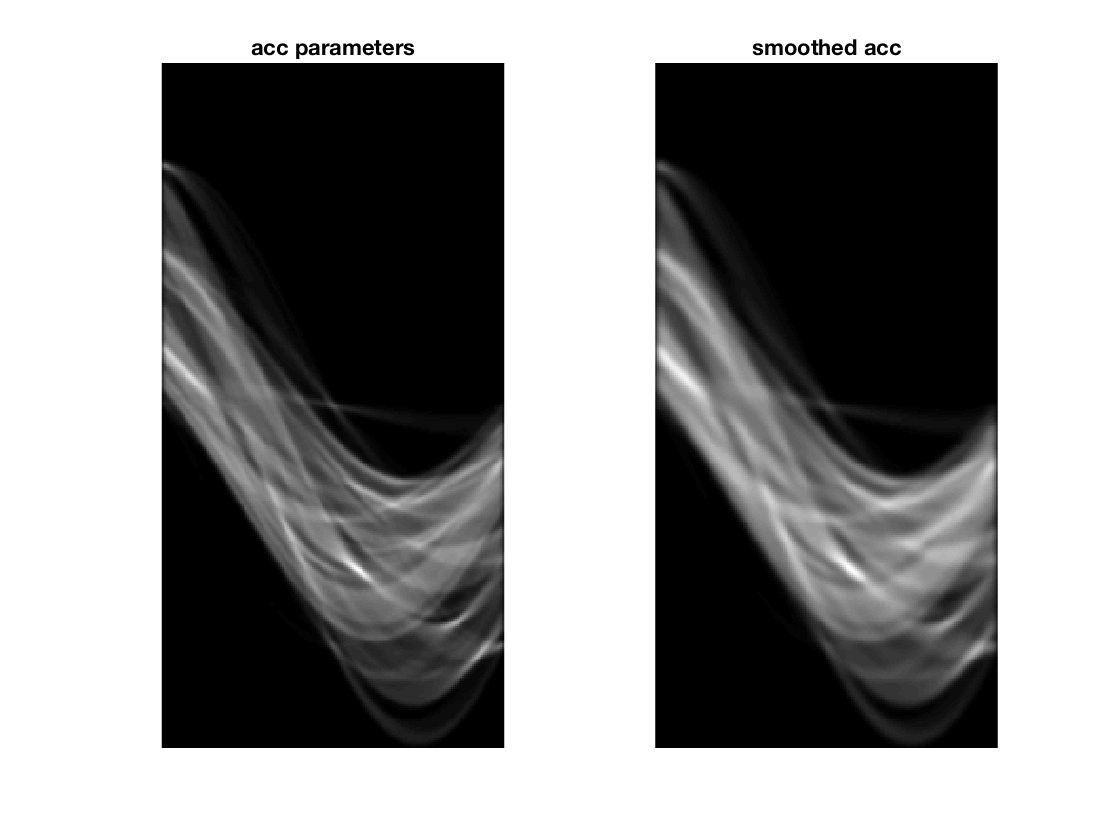

testimage1 = phonecalc256 ;
smalltest = binsubsample(testimage1);
scale = 16;
gradmagnthreshold = 15;
nrho = 360;
ntheta = 180;
nlines = 15;
verbose = 2;
verbose_edge = 1;
[linepar,acc] = houghedgeline(testimage1,scale,gradmagnthreshold,nrho,ntheta,nlines,verbose,verbose_edge);

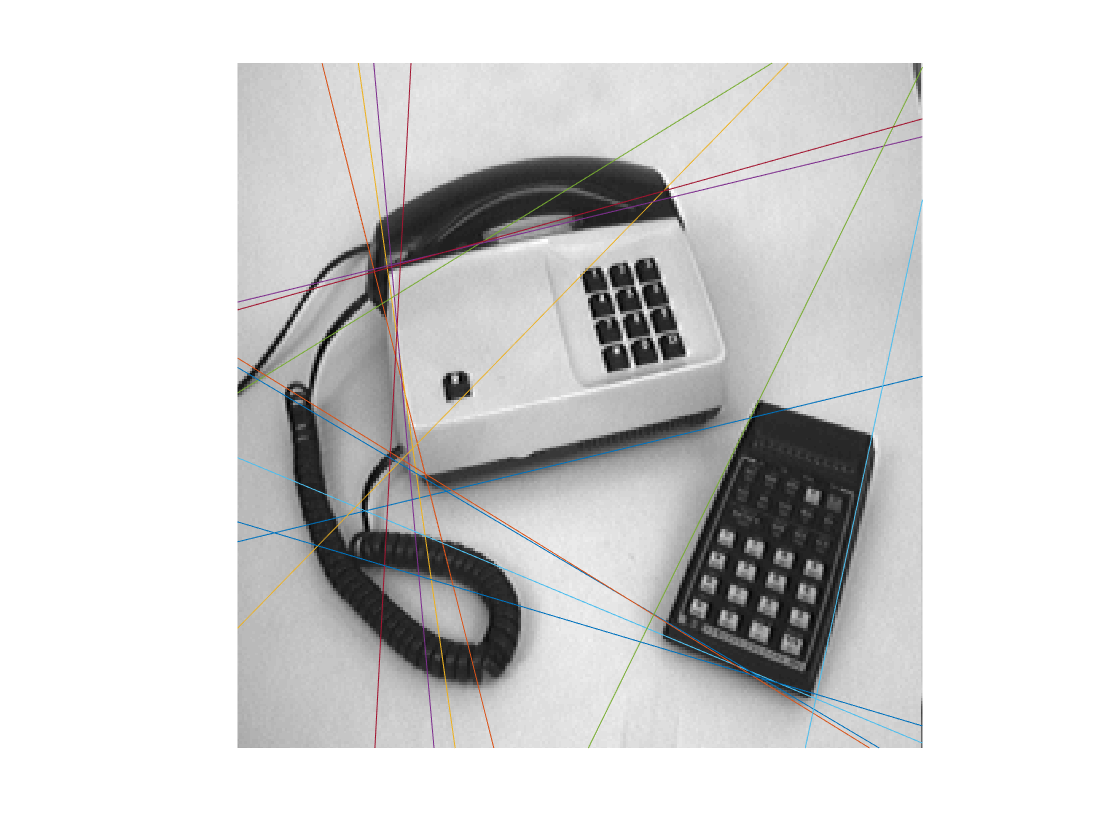

visualize_edge(testimage1,linepar);

**Question 9** :

    How do the results and computational time depend on the number of cells in the accumulator? 

**Answer:**

   If we have more cells in the accumulator, the computational time will increase because we have to iterate all the theta when looking for the lines. On the other hand, if we have more cells in the accumulator, the results will be more accurate because we can find the rho and theta in the accumulator which are closer to the actual rho and theta.

**Question 10:**

    How do you propose to do this? Try out a function that you would suggest and see if it improves the results. Does it? 

**Answer**:

In this question, instead of setting s=1, I also tried the other functions which are: 

- s = 1   

        2.  s = log(magnitude) 

        3. s = magnitude^2 

In first function s = 1, it treats all the magnitude, including the local maxima as equal. On the second function, it will smooth out the importance of large magnitude, which indirectly smooth out the noise. Therefore, the lines in which s = log(magnitude) will be closer to the actual edge. On the other hand, the third function s = magnitude^2 enlarge the importance of the magnitude, hence some lines might locate close not to the edge but to the local maxima. For example, in the image ***few256*** and ***phonecalc256***, when s = magnitude^2, unlike when s = log(magnitude) or s = 1, lines are really close to each other because there is a large magnitude on that line where the accumulator increment is large.

Among these three functions, the second function indeed improve the results. It removes the lines which are caused by local maxima instead of the edge. 

1.***triangle128***

rho = 40.9340

theta = -0.4826

rho = 111.8863

theta = 0.0088

rho = 8.1868

theta = 1.5357

testimage1 = triangle128;
scale = 2;
gradmagnthreshold = 5;
nrho = 200;
ntheta = 180;
nlines = 3;
verbose = 0;

figure

verbose_edge = 1;
[linepar,acc] = houghedgeline(testimage1,scale,gradmagnthreshold,nrho,ntheta,nlines,verbose,verbose_edge);

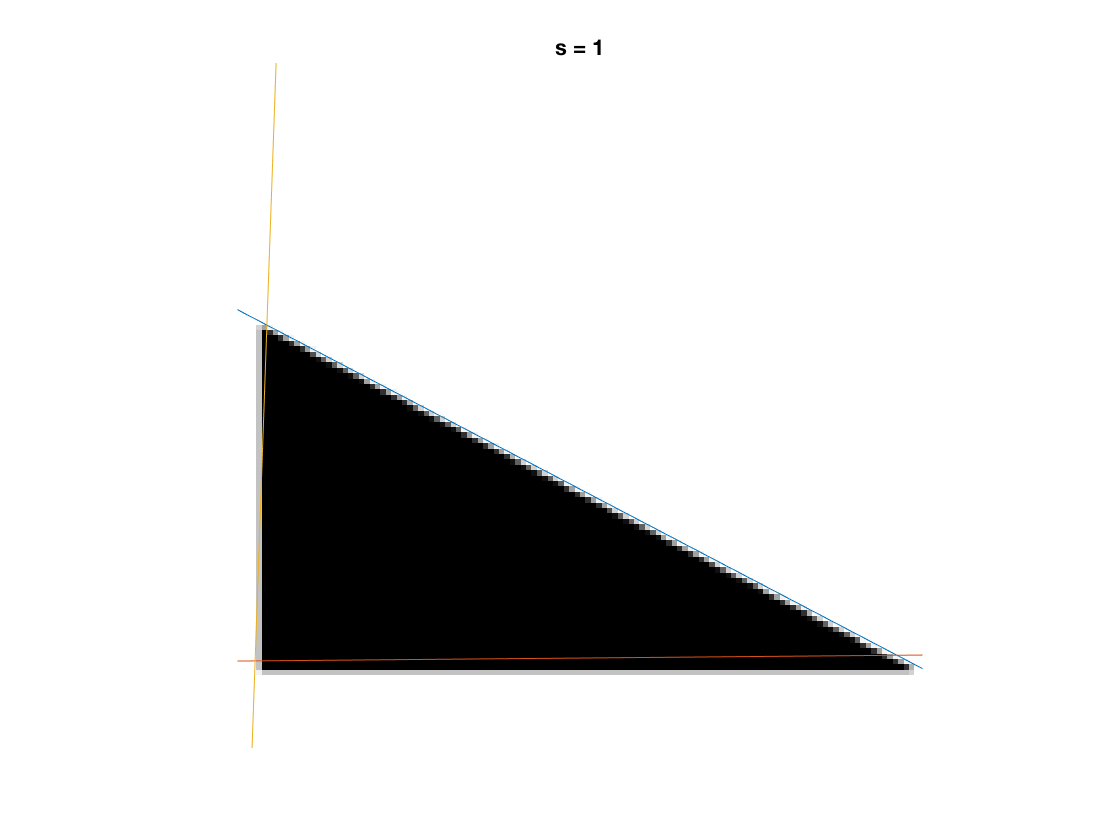

visualize_edge(testimage1,linepar);
title('s = 1')

rho = 40.9340

theta = -0.4826

rho = 111.8863

theta = 0.0088

rho = 8.1868

theta = 1.5357


figure
scale = 2;
gradmagnthreshold = 5;
verbose_edge = 2;
[linepar,acc] = houghedgeline(testimage1,scale,gradmagnthreshold,nrho,ntheta,nlines,verbose,verbose_edge);

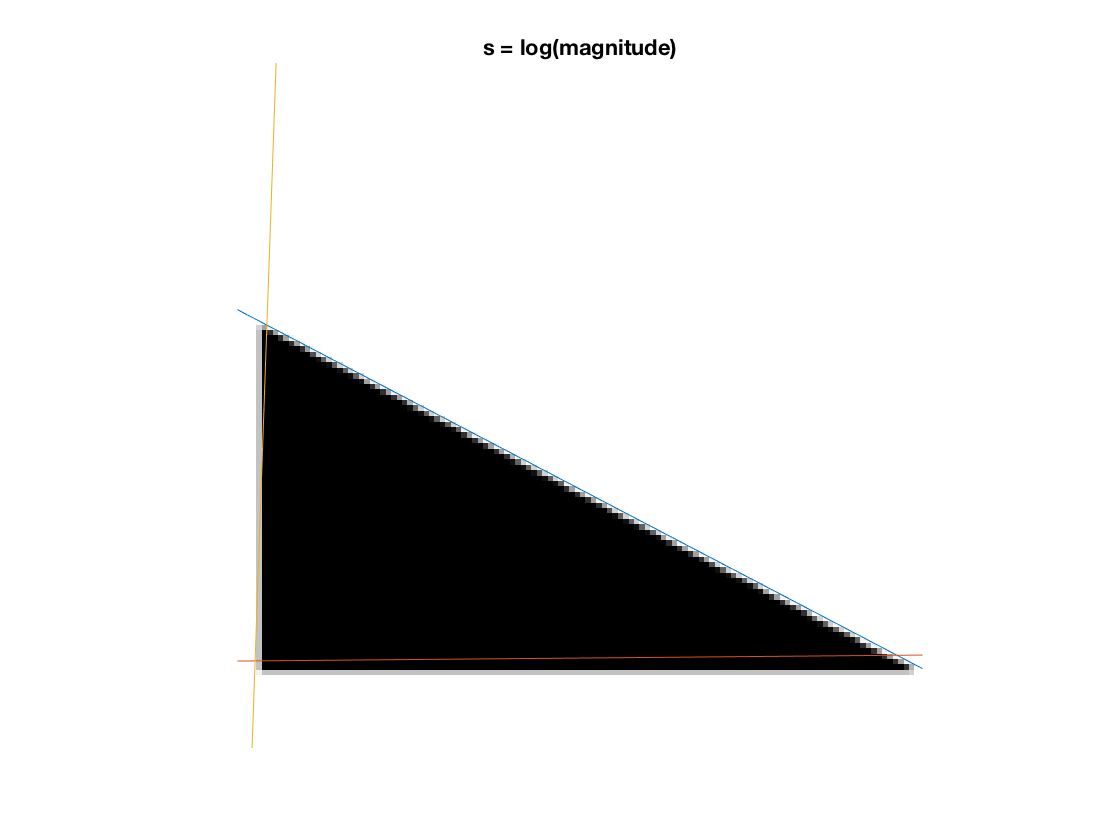

visualize_edge(testimage1,linepar);
title('s = log(magnitude)')

rho = 40.9340

theta = -0.4826

rho = 8.1868

theta = 1.5181

rho = -2.7289

theta = -1.5181

figure
verbose_edge = 3;
[linepar,acc] = houghedgeline(testimage1,scale,gradmagnthreshold,nrho,ntheta,nlines,verbose,verbose_edge);

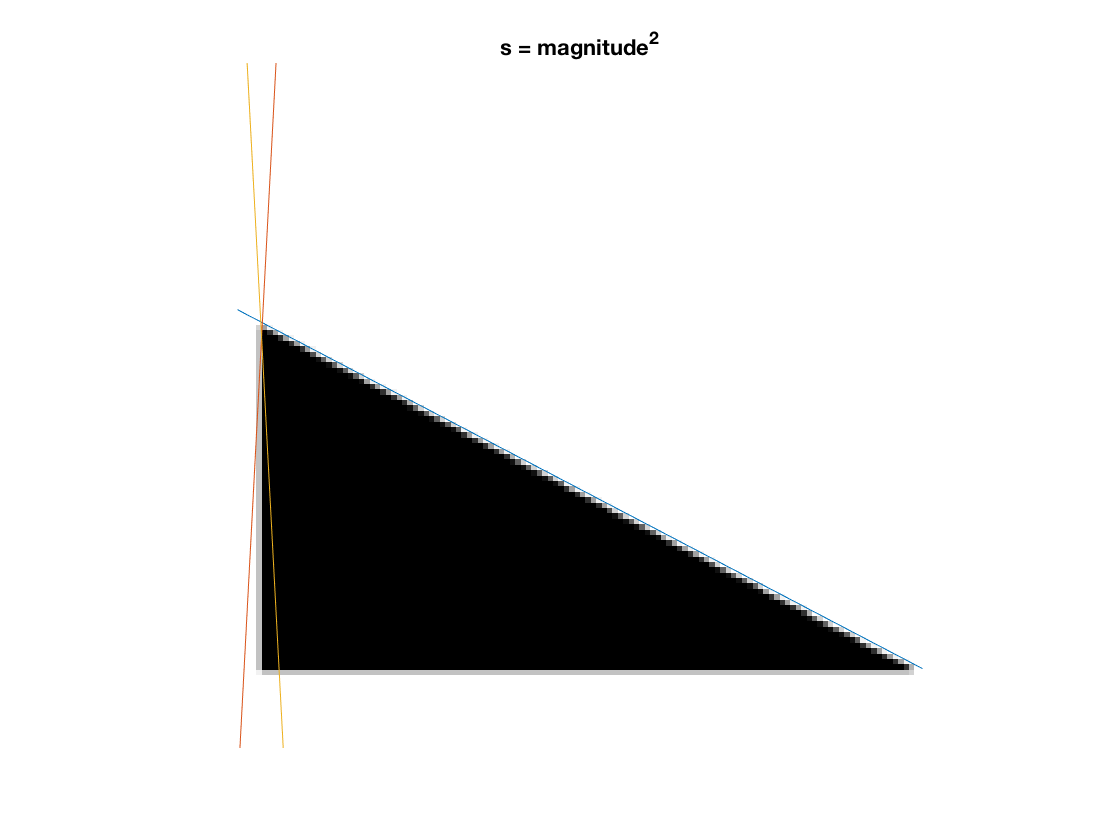

visualize_edge(testimage1,linepar);
title('s = magnitude^2')

2.***houghtest256***

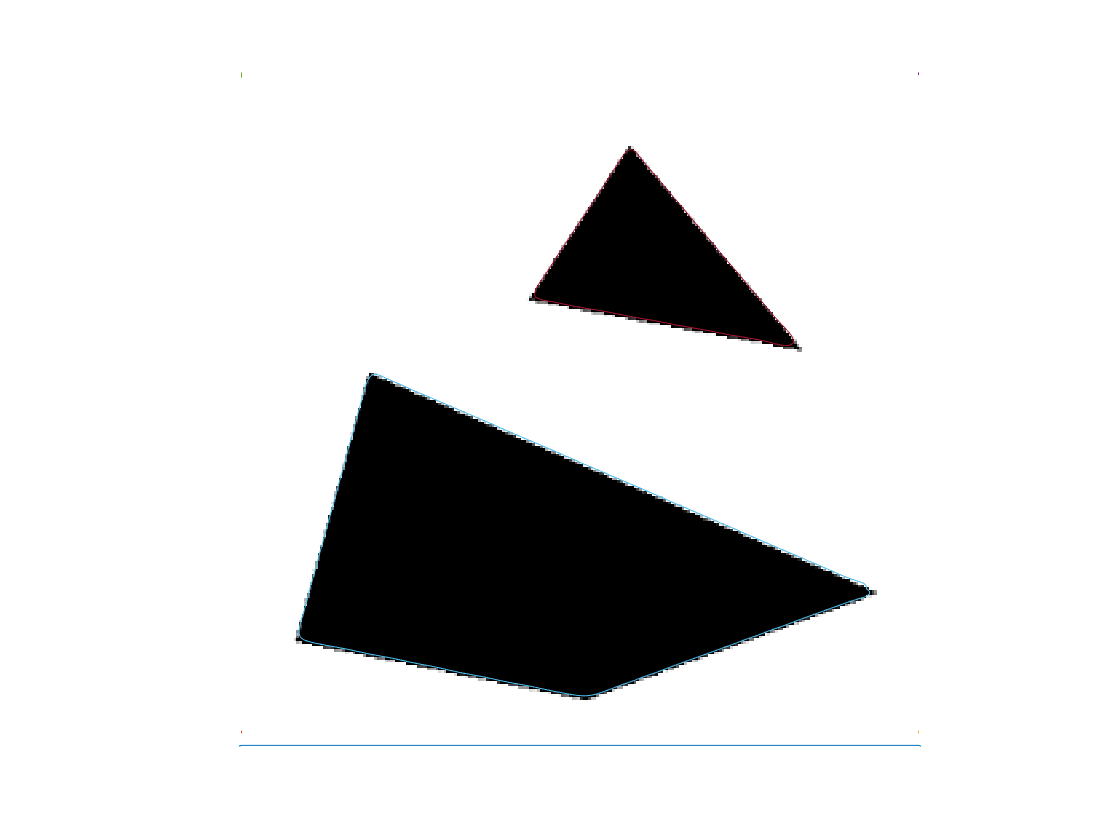

rho = 86.3379

theta = -0.4069

rho = 267.7200

theta = 0.3544

rho = 266.2689

theta = 0.3369

rho = 269.1710

theta = 0.3719

rho = 138.5759

theta = 0.9582

rho = 140.0270

theta = 1.0020

rho = -93.5932

theta = -0.8707

rho = 79.0826

theta = 1.2995

testimage1 = houghtest256;
scale = 8;
gradmagnthreshold = 10;
nrho = 500;
ntheta = 360;
nlines = 8;
verbose = 0;

figure

verbose_edge = 1;
[linepar,acc] = houghedgeline(testimage1,scale,gradmagnthreshold,nrho,ntheta,nlines,verbose,verbose_edge);

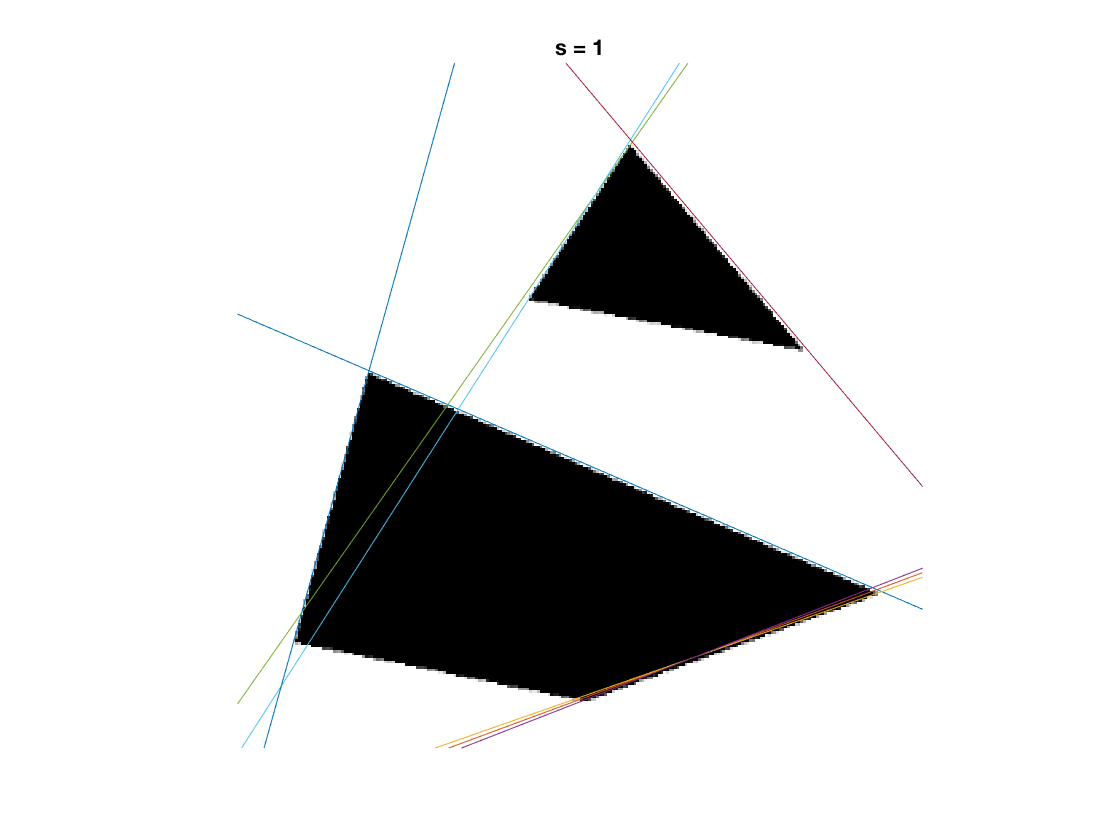

visualize_edge(testimage1,linepar);
title('s = 1')

rho = 86.3379

theta = -0.4069

rho = 267.7200

theta = 0.3544

rho = 266.2689

theta = 0.3369

rho = 138.5759

theta = 0.9582

rho = 269.1710

theta = 0.3719

rho = 140.0270

theta = 1.0020

rho = -95.0442

theta = -0.8795

rho = 79.0826

theta = 1.2995

figure
verbose_edge = 2;
[linepar,acc] = houghedgeline(testimage1,scale,gradmagnthreshold,nrho,ntheta,nlines,verbose,verbose_edge);

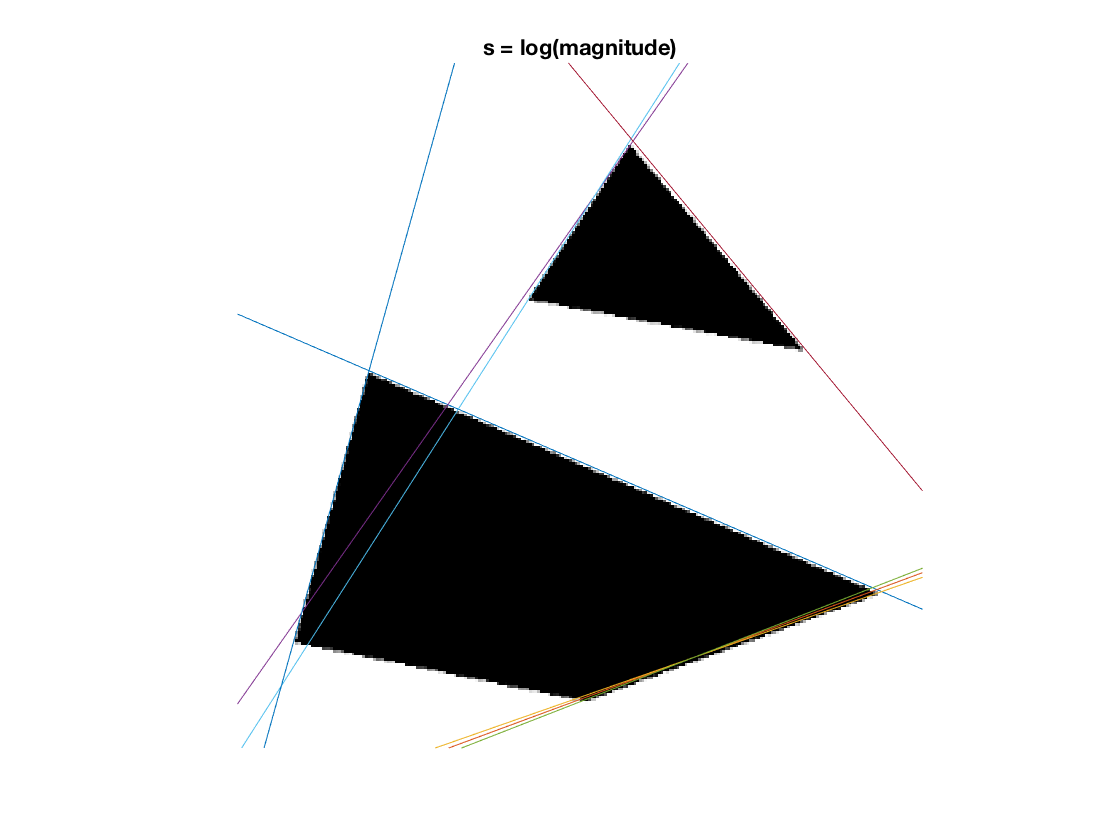

visualize_edge(testimage1,linepar);
title('s = log(magnitude)')

rho = -95.0442

theta = -0.8795

rho = 138.5759

theta = 0.9582

rho = -87.7889

theta = -0.8357

rho = 140.0270

theta = 1.0020

rho = 79.0826

theta = 1.2995

rho = 87.7889

theta = -0.3982

rho = -39.9041

theta = -0.5994

rho = -23.9424

theta = -0.5207

figure
verbose_edge = 3;
[linepar,acc] = houghedgeline(testimage1,scale,gradmagnthreshold,nrho,ntheta,nlines,verbose,verbose_edge);

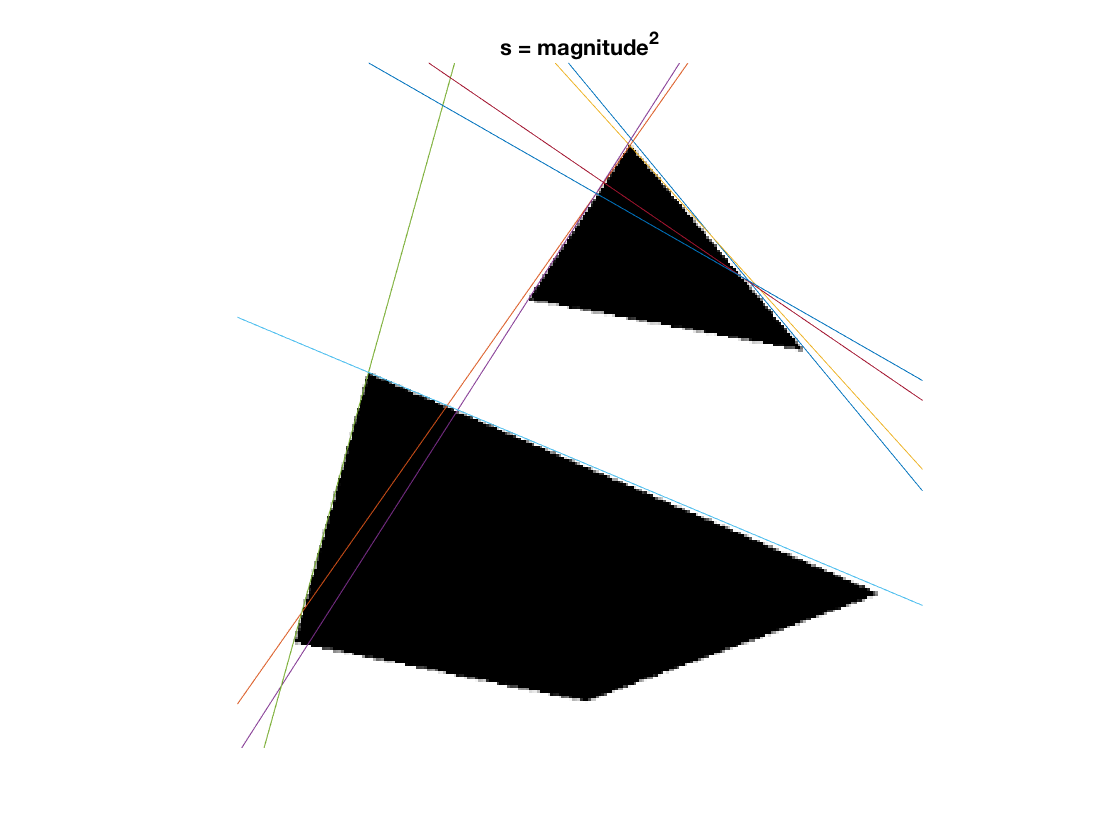

visualize_edge(testimage1,linepar);
title('s = magnitude^2')

3.***few256***

testimage1 = few256;
scale = 5;
gradmagnthreshold = 20;
nrho = 500;
ntheta = 360;
nlines = 10;
verbose = 0;

figure

verbose_edge = 1;
[linepar,acc] = houghedgeline(testimage1,scale,gradmagnthreshold,nrho,ntheta,nlines,verbose,verbose_edge);
visualize_edge(testimage1,linepar);
title('s = 1')
figure
verbose_edge = 2;
[linepar,acc] = houghedgeline(testimage1,scale,gradmagnthreshold,nrho,ntheta,nlines,verbose,verbose_edge);
visualize_edge(testimage1,linepar);
title('s = log(magnitude)')
figure
verbose_edge = 3;
[linepar,acc] = houghedgeline(testimage1,scale,gradmagnthreshold,nrho,ntheta,nlines,verbose,verbose_edge);
visualize_edge(testimage1,linepar);
title('s = magnitude^2')

4.*** phonecal256***

testimage1 = phonecalc256;
scale = 16;
gradmagnthreshold = 15;
nrho = 500;
ntheta = 360;
nlines = 15;
verbose = 0;

figure

verbose_edge = 1;
[linepar,acc] = houghedgeline(testimage1,scale,gradmagnthreshold,nrho,ntheta,nlines,verbose,verbose_edge);
visualize_edge(testimage1,linepar);
title('s = 1')
figure
verbose_edge = 2;
[linepar,acc] = houghedgeline(testimage1,scale,gradmagnthreshold,nrho,ntheta,nlines,verbose,verbose_edge);
visualize_edge(testimage1,linepar);
title('s = log(magnitude)')
figure
verbose_edge = 3;
[linepar,acc] = houghedgeline(testimage1,scale,gradmagnthreshold,nrho,ntheta,nlines,verbose,verbose_edge);
visualize_edge(testimage1,linepar);